clear;
noise_type_str = ["NO NOISE", "BIT FLIP", "DEPOLARIZING", "DEPHASING", "AMPLITUDE DAMPING"];


noise_p=0.001;
lambda=2;
offset=2;
dt=0.005;
nqubits=9;
init_cond=1;

## 提取$u_\mathrm{main}$

### 对每个 t, 拟合 u

对每个时刻t，拟合模型$u(x,t;D,E,F,G)=D\sin(E(x-Ft))+G$

modelEq = '$\ u(x,t;D,E,F,G)=D\sin(E(x-Ft))+G$';
function v = diffusion_model(p,x,t,lambda)
    D=p(1);
    E=p(2);
    F=p(3);
    G=p(4);
    v = D*sin(E*(x-F*t))+G ;
end

fig_fit = figure(Position=[0,0,1280,680]);
noise_types_list = [1,2,3,4];

for noise_type=noise_types_list
    name = strcat(noise_type_str(noise_type+1), num2str(noise_p),...
        '_lambda',num2str(lambda),...
        '_offset',num2str(offset),...
        '_dt', num2str(dt),...
        '_nqubits',num2str(nqubits),...
        '_initCond',num2str(init_cond));
    load(strcat('DATA/MAT_',name,'.mat'));
    
    % Fitting data to single wave modelEq
    D_opt = zeros(params.nsteps,1);
    E_opt = zeros(params.nsteps,1);
    F_opt = zeros(params.nsteps,1);
    G_opt = zeros(params.nsteps,1);
    resnorms = zeros(params.nsteps,1);% resnorm is the squared 2-norm of the residual(残差) at x: sum((fun(x,xdata)-ydata).^2).
    for i = 1:params.nsteps
        ui = u(i+1,:);
        % D E F G
        p_initial = [1.0, params.lambda, params.c,  params.offset];
        lb =        [0,   0,             0,         -Inf         ];
        ub =        [Inf, Inf,           2*pi,      Inf          ];
        options = optimoptions('lsqcurvefit', 'Display', 'iter', 'Algorithm','trust-region-reflective');
        [p_opt, resnorms(i)]=lsqcurvefit(@(p,x)diffusion_model(p,x,params.dt*(i),params.lambda), p_initial, x, ui, lb, ub, options);
        D_opt(i) = p_opt(1);
        E_opt(i) = p_opt(2);
        F_opt(i) = p_opt(3);
        G_opt(i) = p_opt(4);
    end
    save(strcat('DATA/SingleFit_',name,'.mat'),"D_opt","E_opt","F_opt","G_opt","resnorms","params","u");

    % Plot
    subplot(2,6,1:3);
    hold on;
    plot(t(2:end), D_opt, 'DisplayName',noise_type_str(noise_type+1),'LineWidth',1.0);
    hold off;
    
    subplot(2,6,7:8);
    hold on;
    plot(t(2:end),E_opt(1:end),LineWidth=1,DisplayName=noise_type_str(noise_type+1));
    hold off;
    
    subplot(2,6,9:10);
    hold on;
    plot(t(2:end),F_opt(1:end),LineWidth=1,DisplayName=noise_type_str(noise_type+1));
    hold off;
    
    subplot(2,6,4:6);
    hold on;
    plot(t(2:end),G_opt(1:end),LineWidth=1,DisplayName=noise_type_str(noise_type+1));
    hold off;
    
    subplot(2,6,11:12);
    hold on;
    plot(t(2:end),sqrt(resnorms(1:end)),LineWidth=1,DisplayName=noise_type_str(noise_type+1));
    hold off;
end


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          5         0.0089442                             1.37
     1         10       0.000725705       0.0181275          0.00721      
     2         15       0.000725493     0.000935382         1.53e-06      

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>

                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       op

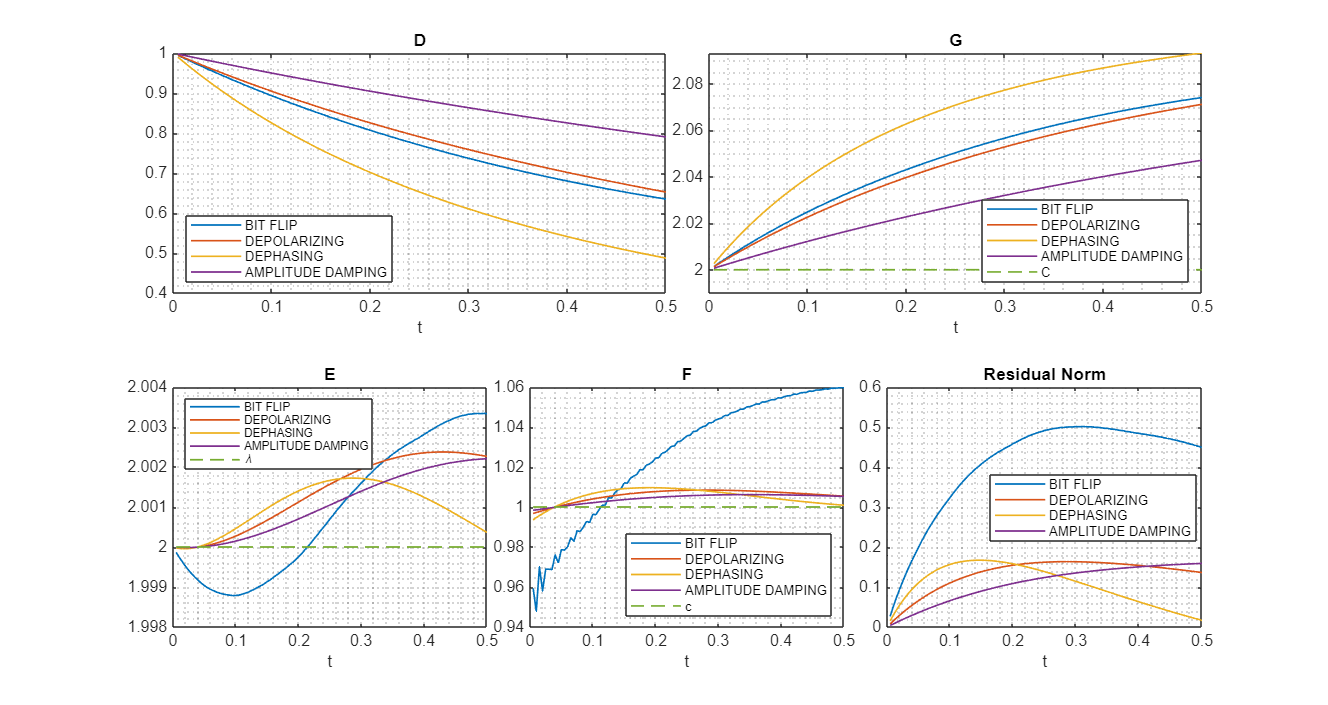

% Adjust format
subplot(2,6,1:3);
box on; grid minor;
legend(Location="southwest", FontSize=8);
xlabel('t');
title('D');

subplot(2,6,7:8);
hold on;
plot(t(2:end),ones(1,length(t)-1)*lambda, '--', DisplayName='\lambda',LineWidth=1);
hold off;
legend(Location="northwest",FontSize=7);
xlabel('t');
title('E')
box on; grid minor;

subplot(2,6,9:10);
hold on;
plot(t(2:end),ones(1,length(t)-1)*params.c, '--', DisplayName='c',LineWidth=1);
hold off;
legend(Location="southeast",FontSize=8);
xlabel('t');
title('F')
box on; grid minor;
    
subplot(2,6,4:6);
hold on;
plot(t(2:end),ones(1,length(t)-1)*offset, '--', DisplayName='C',LineWidth=1);
hold off;
ylim([offset-0.01, +Inf])
legend('location','southeast',FontSize=8)
xlabel('t');
title('G')
box on; grid minor;
    
subplot(2,6,11:12);
xlabel('t');
title('Residual Norm')
box on; grid minor;
legend(Location="best",FontSize=8);
% Save figure
figname=strcat('p', num2str(noise_p),...
    '_lambda',num2str(lambda),...
    '_offset',num2str(offset),...
    '_dt', num2str(dt),...
    '_nqubits',num2str(nqubits));
savefig(fig_fit, strcat('FIG/SingleFit_', figname,'.fig'))
exportgraphics(fig_fit, strcat('FIG/SingleFit_', figname,'.pdf'));

## 提取$u_\mathrm{main}$

### 对每个 t, 拟合 u

对每个时刻t，拟合模型$u(x,t;D,G)=D\sin(\lambda(x-ct))+G$

modelEq2 = '$\ u(x,t;D,G)=D\sin(\lambda(x-ct))+G$';
function v = u_model2(p,x,t)
    lambda = evalin("base", "lambda");
    c = evalin("base", "params.c");
    D=p(1);
    G=p(2);
    v = D*sin(lambda*(x-c*t))+G ;
end

### 以t为变量，拟合D,G


$$ D_\mathrm{main}(t;P,Q,R)=Pe^{Qt}+R, \\
        G_\mathrm{main}(t;X,Y,Z)=Xe^{Yt}+Z,$$


modelEq_D = '$\ D(t)=Pe^{Qt}+R$';
function v = D_model(p,t)
    P=p(1);
    Q=p(2);
    R=p(3);
    v = P*exp(Q*t)+R ;
end
modelEq_G = '$\ G(t)=Xe^{Yt}+Z$';
function v = G_model(p,t)
    P=p(1);
    Q=p(2);
    R=p(3);
    v = P*exp(Q*t)+R ;
end

fig_fit2 = figure(Position=[0,0,1280,384]);
noise_types_list = [1,2,3,4];
D_resnorms = zeros(length(noise_types_list),1);
G_resnorms = zeros(length(noise_types_list),1);
for i=1:length(noise_types_list)
    noise_type=noise_types_list(i)
    name = strcat(noise_type_str(noise_type+1), num2str(noise_p),...
        '_lambda',num2str(lambda),...
        '_offset',num2str(offset),...
        '_dt', num2str(dt),...
        '_nqubits',num2str(nqubits),...
        '_initCond',num2str(init_cond));
    load(strcat('DATA/MAT_',name,'.mat'));
    
    % Fitting data to single wave modelEq2
    D_opt = zeros(params.nsteps,1);
    G_opt = zeros(params.nsteps,1);
    u_resnorms = zeros(params.nsteps,1);% resnorm is the squared 2-norm of the residual(残差) at x: sum((fun(x,xdata)-ydata).^2).
    for j = 1:params.nsteps
        ui = u(j+1,:);
        % D G
        p_initial = [1.0, params.offset];
        lb =        [0,   -Inf         ];
        ub =        [Inf, Inf          ];
        options = optimoptions('lsqcurvefit', 'Display', 'iter', 'Algorithm','trust-region-reflective');
        [p_opt, u_resnorms(j)]=lsqcurvefit(@(p,x)u_model2(p,x,params.dt*(j)), p_initial, x, ui, lb, ub, options);
        D_opt(j) = p_opt(1);
        G_opt(j) = p_opt(2);
    end

    % Fitting data to modelEq_D
    %             [P    Q      R    ]
    p_initial_D = [1.0, -1,    1  ];
    lb =          [0,   -Inf,  0    ];
    ub =          [Inf, 0,     Inf  ];
    options = optimoptions('lsqcurvefit', 'Display', 'iter', 'Algorithm','trust-region-reflective');
    [p_opt_D, D_resnorm]=lsqcurvefit(@(p,t)D_model(p,t), p_initial_D, t(2:end)', D_opt, lb, ub, options);
    P=p_opt_D(1);
    Q=p_opt_D(2);
    R=p_opt_D(3);
    D_resnorms(i)=D_resnorm;

    % Fitting data to modelEq_G
    %             [X        Y                Z    ]
    p_initial_G = [1.0,     -1,              1  ];
    lb =          [-Inf,    -Inf,            0 ];
    ub =          [0,       0,               Inf  ];
    options = optimoptions('lsqcurvefit', 'Display', 'iter', 'Algorithm','trust-region-reflective');
    [p_opt_G, G_resnorm]=lsqcurvefit(@(p,t)G_model(p,t), p_initial_G, t(2:end)', G_opt, lb, ub, options);
    X=p_opt_G(1);
    Y=p_opt_G(2);
    Z=p_opt_G(3);
    G_resnorms(i)=G_resnorm;

    save(strcat('DATA/SingleFit2_',name,'.mat'),"D_opt","G_opt", ...
        "u_resnorms","params", ...
        "u","X","Y","Z","P","Q","R","D_resnorm","G_resnorm");

    % Plot
    subplot(1,3,1);
    hold on;
    plot(t(2:end), D_opt, 'DisplayName',noise_type_str(noise_type+1),'LineWidth',1.2);
    plot(t,D_model(p_opt_D,t),'--', 'DisplayName',strcat(noise_type_str(noise_type+1), " fitted") ,'LineWidth', 0.8);
    hold off;

    subplot(1,3,2);
    hold on;
    plot(t(2:end),G_opt(1:end),LineWidth=1.2,DisplayName=noise_type_str(noise_type+1));
    plot(t,G_model(p_opt_G,t),'--', 'DisplayName',strcat(noise_type_str(noise_type+1), " fitted"), 'LineWidth', 0.8);
    hold off;
end

noise_type = 1


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          3         0.0089442                             1.37
     1          6       0.000740914      0.00547474          0.00722      
     2          9       0.000740708     2.84279e-05         2.06e-07      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

                                            Norm of      First-order 
 Iteration  Func-count      Resnorm


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           100.305                              100
     1          8            18.693         3.32498             36.5      
     2         12           3.32059         4.58634             13.3      
     3         16          0.377501         1.94103             2.02      
     4         20         0.0939701         6.11114             1.62      
     5         24         0.0212852         0.89952            0.385      
     6         28         0.0150576        0.971133             0.53      
     7         32        0.00292583         0.06864           0.0182      
     8         36        0.00154293        0.242783            0.128      
     9         40        0.00043242        0.108929           0.0171      
    10         44       0.000228063        0.235271           0.0562      
    11         48       2.19477e-05      


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           207.096                              144
     1          8         0.0204503         1.72523             1.11      
     2         12        0.00134259        0.124856           0.0305      
     3         16        0.00131968       0.0128789          0.00121      
     4         20        0.00131968        0.203501          0.00121      
     5         24        0.00130355       0.0508752           0.0119      
     6         28        0.00129082       0.0293114          0.00456      
     7         32        0.00127016       0.0753424           0.0287      
     8         36        0.00125227       0.0169109          0.00185      
     9         40        0.00124331         0.10175           0.0556      
    10         44        0.00119545       0.0162805          0.00157      
    11         48        0.00118199      

noise_type = 2


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          3        0.00800458                             1.34
     1          6       6.05966e-05      0.00538786          0.00699      
     2          9       6.04036e-05     2.75287e-05         1.93e-07      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

                                            Norm of      First-order 
 Iteration  Func-count      Resnorm


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           96.9639                             98.5
     1          8           17.7326         3.22994             35.4      
     2         12           2.97584         4.16177             12.2      
     3         16          0.351857         1.55025              1.7      
     4         20         0.0720478           5.416             1.35      
     5         24         0.0247567          1.1566            0.538      
     6         28        0.00827007        0.429286            0.186      
     7         32        0.00543755         0.54809            0.256      
     8         36        0.00182702       0.0507027           0.0123      
     9         40        0.00122213        0.137023           0.0191      
    10         44       0.000845476        0.274045           0.0871      
    11         48       0.000265042      


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           206.236                              144
     1          8         0.0217898         1.73175             1.15      
     2         12       0.000869893        0.130661           0.0336      
     3         16       0.000845687       0.0100331         0.000751      
     4         20       0.000845687        0.229423         0.000751      
     5         24       0.000833327       0.0573557           0.0147      
     6         28       0.000825364       0.0181412          0.00183      
     7         32       0.000825364        0.125833          0.00183      
     8         36        0.00081717       0.0286779          0.00396      
     9         40       0.000802462       0.0680965           0.0235      
    10         44       0.000790279       0.0154649          0.00151      
    11         48        0.00077384      

noise_type = 3


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          3         0.0316878                             2.68
     1          6       0.000236015       0.0106706           0.0274      
     2          9       0.000233017      0.00010878            3e-06      
     3         12       0.000233017     1.18978e-08         2.32e-10      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

                              


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           122.445                              111
     1          8           25.7223         3.92255             43.9      
     2         12           6.60274         7.42425             20.2      
     3         16          0.826631         2.83222             3.66      
     4         20          0.452651              10             3.43      
     5         24         0.0794029        0.918472            0.285      
     6         28         0.0794029         1.12871            0.285      
     7         32         0.0486526        0.282176            0.218      
     8         36         0.0258204        0.564353            0.538      
     9         40         0.0056857        0.316426           0.0839      
    10         44        0.00279027         0.58829             0.16      
    11         48        0.00037691      


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           212.147                              146
     1          8         0.0150407         1.68882            0.853      
     2         12        0.00417063         0.09493           0.0176      
     3         16        0.00412391       0.0487466           0.0139      
     4         20        0.00406785       0.0640953           0.0231      
     5         24        0.00401645       0.0460151           0.0128      
     6         28        0.00394202       0.0866945           0.0443      
     7         32         0.0038754        0.036901          0.00856      
     8         36         0.0038754        0.161153          0.00856      
     9         40        0.00382536       0.0402882          0.00945      
    10         44        0.00373579       0.0805764            0.038      
    11         48        0.00363222      

noise_type = 4


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          3        0.00201229                            0.674
     1          6       1.54021e-05      0.00270772          0.00177      
     2          9       1.53899e-05     6.92676e-06         1.23e-08      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

                                            Norm of      First-order 
 Iteration  Func-count      Resnorm


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           81.0707                             89.9
     1          8           13.5536         2.69848             29.5      
     2         12           1.90665         2.15762             7.15      
     3         16          0.321924        0.649943            0.638      
     4         20         0.0271459        0.812181            0.454      
     5         24        0.00599751        0.264057           0.0844      
     6         28        0.00599751        0.527228           0.0844      
     7         32        0.00473855        0.131807           0.0288      
     8         36         0.0032599        0.263614            0.128      
     9         40        0.00219837        0.263614           0.0734      
    10         44        0.00219837        0.401618           0.0734      
    11         48        0.00174953      


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           201.446                              142
     1          8          0.625482         1.72631             7.85      
     2         12       0.000138158        0.149982           0.0382      
     3         16       0.000111609      0.00553655         0.000121      
     4         20       0.000111609         0.21097         0.000121      
     5         24       0.000110345       0.0527426          0.00867      
     6         28       0.000109134      0.00456454         0.000112      
     7         32       0.000107793       0.0527426          0.00938      
     8         36       0.000106391      0.00473805         0.000128      
     9         40       0.000104977       0.0527426           0.0101      
    10         44       0.000103344      0.00497748         0.000147      
    11         48       0.000101853      

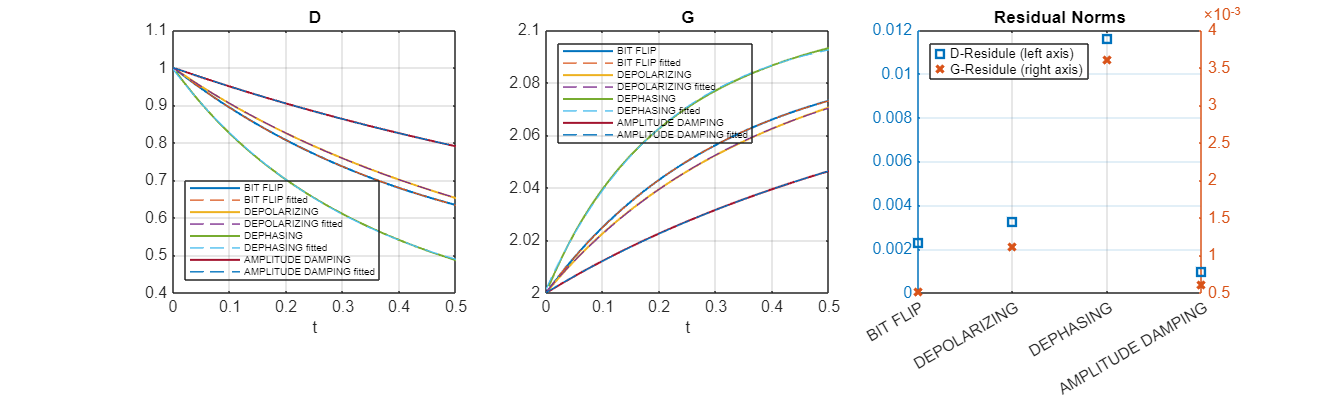

% Adjust format
subplot(1,3,1);
box on; grid on;
legend(Location="southwest", Color='none',FontSize=6); 
xlabel('t');
title('D');
    
subplot(1,3,2);
legend('location','northwest',Color='none', FontSize=6)
xlabel('t');
title('G')
box on; grid on;
    
subplot(1,3,3);
hold on;
yyaxis right;
scatter(1:length(noise_types_list),sqrt(G_resnorms),Marker="x", LineWidth=2, DisplayName="G-Residule (right axis)");
yyaxis left;
scatter(1:length(noise_types_list),sqrt(D_resnorms),Marker="square",LineWidth=2, DisplayName="D-Residule (left axis)");
hold off;

title('Residual Norms')
xticks(1:length(noise_types_list)); xticklabels(noise_type_str(noise_types_list+1));
box on; grid on;
legend(Location="northwest",FontSize=8);

% Save figure
figname=strcat('p', num2str(noise_p),...
    '_lambda',num2str(lambda),...
    '_offset',num2str(offset),...
    '_dt', num2str(dt),...
    '_nqubits',num2str(nqubits));
savefig(fig_fit2, strcat('FIG/SingleFit2_', figname,'.fig'))
exportgraphics(fig_fit2, strcat('FIG/SingleFit2_', figname,'.pdf'));